# 14주차 — 관측기와 분리원리: 못 재는 상태를 만들어 낸다

**제어시스템설계** · 충남대학교 자율운항시스템공학과

**참고자료 — 먼저 볼 것**

아래 다섯 과목은 **이 강의의 담당교수가 직접 한 강의**입니다. 기초부터 대학원 과정까지 이어지므로 부족한 곳부터 보면 됩니다. 이 강의에서 쓰는 기호와 유도는 모두 그 안에서 자세히 다룹니다.

**MATLAB 이나 Simulink 가 아직 익숙하지 않다면** 실습에 들어가기 전에 아래를 먼저 하십시오. 무료이고 각각 몇 시간이면 끝납니다.

13주차 내내 $u = -Kx$ 를 썼습니다. 그러려면 **상태를 전부 알아야** 합니다.

그런데 현실은 이렇습니다.

- DC 모터에서는 각도만 잰다. 전류를 재려면 센서를 더 달아야 한다

- 진자에서는 각도만 잰다. 자이로는 비싸고 잡음이 많다

오늘 그 문제를 풉니다. **없는 센서를 계산으로 대신합니다.**

if isempty(which('plant_msd'))   % 경로가 아직 등록 안 되었으면 알아서 잡는다
    p_ = pwd;
    if ~isempty(mfilename('fullpath')), p_ = fileparts(mfilename('fullpath')); end
    for k_ = 1:4
        if isfile(fullfile(p_,'setup_path.m')), run(fullfile(p_,'setup_path.m')); break; end
        p_ = fileparts(p_);
    end
    clear p_ k_
end
clc; close all;
s = tf('s');

## 0-0. 오늘 돌려 볼 파일

강의노트를 읽다가 **직접 값을 바꿔 보고 싶을 때** 여는 파일들입니다. 모두 `W14_Observer` 폴더 안에 있습니다.

오늘 처음 쓰는 도우미 함수도 하나 있습니다.

실행하는 법 — 파일을 열고 절 안에서 `Ctrl+Enter` 를 누르면 그 절만 돕니다. 전체는 `F5` 입니다. 처음 한 번은 `setup_path` 를 먼저 실행하십시오.

이 강의노트의 **그림은 전부** `make_figures.m` 이 만들어 `common/figures/` 에 넣어 둔 것입니다. 그림마다 어느 함수가 만들었는지 아래에 적어 두었습니다.

## 0. 오늘 한 장 요약

오늘 배우는 것을 한 문장으로 적으면 이렇습니다.

**같은 모델을 컴퓨터 안에서 함께 돌리고, 잰 출력과 예상한 출력의 차이를 보고 추정을 고치면, 못 재는 상태를 만들어 낼 수 있다.**

오늘의 계단

- **1~3절** 관측기란 무엇인가. 전치 트릭

- **4~6절** 추정오차는 스스로 줄어든다. 얼마나 빠르게 잡을 것인가

- **7~10절** 분리원리 — **따로 설계해도 된다**

- **11절** Simulink 로 실제와 추정을 나란히

- **12절** 한 학기 되짚기

오늘 딱 하나만 기억한다면 이것입니다.

- **제어기와 관측기를 따로 설계해도 된다** (분리원리)

## 0-1. 가장 작은 예부터 — 없는 값을 어떻게 아는가

이해를 돕기 위해 비유부터 봅니다.

차 안에 속도계가 고장 났다고 합니다. GPS 위치는 나옵니다. 속도를 어떻게 알 수 있는가?

- **방법 1** — 위치를 미분한다. 그런데 GPS 에 잡음이 있어 미분하면 폭발한다 (7주차에서 본 그 문제입니다)

- **방법 2** — 차의 **모델**을 안다면, 액셀을 얼마나 밟았는지로 속도를 계산할 수 있다. 그런데 모델이 조금 틀리면 계속 어긋난다

- **방법 3** — 모델로 계산하되, **GPS 위치와 내가 계산한 위치의 차이**를 보고 계속 고친다

**방법 3이 관측기입니다.** 미분하지 않으므로 잡음에 강하고, 오차를 보고 고치므로 모델이 조금 틀려도 됩니다.

지금까지 열세 주 동안 "오차를 보고 고친다" 를 배웠습니다. 오늘은 그 발상을 **제어가 아니라 추정에** 씁니다.

## 1. 관측기 — 같은 모델을 함께 돌린다

실제 플랜트가


$$\dot{x} = Ax + Bu, \qquad y = Cx$$


라면, 컴퓨터 안에서도 똑같이 돌립니다.


$$\dot{\hat{x}} = A\hat{x} + Bu$$


입력 $u$ 는 우리가 만든 것이니 당연히 압니다.

**그런데 이것만으로는 안 됩니다.** 초기값이 다르면 영영 어긋난 채로 갑니다. 이것을 **열린 관측기**라 하고, 실무에서 쓰면 안 되는 것입니다.

그래서 한 항을 더합니다.


$$\dot{\hat{x}} = A\hat{x} + Bu + L\,(y - C\hat{x})$$


마지막 항을 읽어 보십시오.

- $y$ — 실제로 **잰** 출력

- $C\hat{x}$ — 내가 **예상한** 출력

- 그 차이가 나면 그만큼 추정을 고친다

**오차를 보고 고친다** — 1주차부터 해 온 그것입니다. 다만 이번에는 제어가 아니라 **추정**에 씁니다.

## 2. 추정오차의 방정식 — 두 줄이면 나옵니다

추정오차를 $e = x - \hat{x}$ 로 두고 두 식을 뺍니다.


$$\dot{e} = (Ax + Bu) - \left(A\hat{x} + Bu + L(Cx - C\hat{x})\right)$$



$$\dot{e} = A(x - \hat{x}) - LC(x - \hat{x}) = (A - LC)\,e$$


**입력 **$u$** 가 사라졌습니다.** 이것이 결정적입니다.

- 무슨 입력을 넣든 추정오차는 **스스로** 줄어든다

- 지령을 바꿔도, 외란이 들어와도 관측기는 제 할 일을 한다

조건은 하나 — $A - LC$ 의 고유값이 전부 좌반면에 있어야 합니다. 그리고 그 고유값을 우리가 정할 수 있는지가 **가관측성**입니다 (12주차).

말로만 하면 잘 안 믿깁니다. 숫자로 확인하겠습니다.

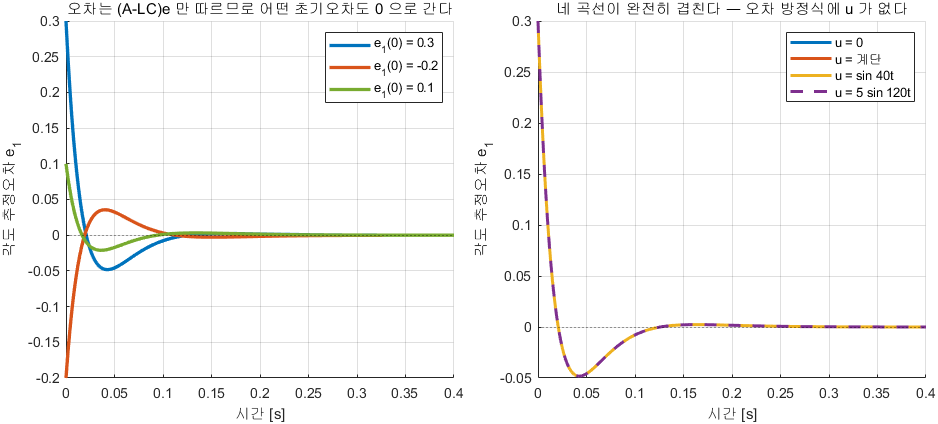

추정오차는 초기값에도 입력에도 흔들리지 않는다

**그림 파일** `w14_error_dyn.png` — `make_figures.m` 의 `fig_w14_error_dyn` · 다시 만들려면 `make_figures('w14_error_dyn')`

**만드는 곳** — `make_figures.m` 의 `fig_w14_error_dyn` **직접 확인해 보려면** — `W14_01_observer.m` 의 **3절**이 초기 추정오차를 바꿔 가며 같은 확인을 합니다

그림 해석

오른쪽 그림이 왜 중요한가 — 관측기는 제어기가 무엇을 하든 **상관없이** 제 할 일을 합니다. 이 성질이 7절의 **분리원리**를 가능하게 합니다.

## 3. 전치 트릭 — 왜 `place(A', C', p)'` 인가

13주차의 `place` 는 $A - BK$ 를 다뤘는데 지금은 $A - LC$ 라 모양이 다릅니다.

그런데 전치해도 고유값은 안 변합니다.


$$\mathrm{eig}(A - LC) = \mathrm{eig}\left((A - LC)^{T}\right) = \mathrm{eig}\left(A^{T} - C^{T}L^{T}\right)$$


오른쪽을 보십시오. $A^{T}$ 를 $A$ 로, $C^{T}$ 를 $B$ 로, $L^{T}$ 를 $K$ 로 놓으면 **13주차와 완전히 같은 문제**입니다.

그래서


$$L = \mathrm{place}(A^{T},\; C^{T},\; p_{obs})^{T}$$


**전치를 두 번 하는 것이 전부입니다.**

이렇게 두 문제가 짝을 이루는 것을 **쌍대성**이라 부릅니다.

**마지막 줄까지 대칭입니다.** 6절에서 확인합니다.

이 표를 그림으로 보면 대응이 더 분명합니다.

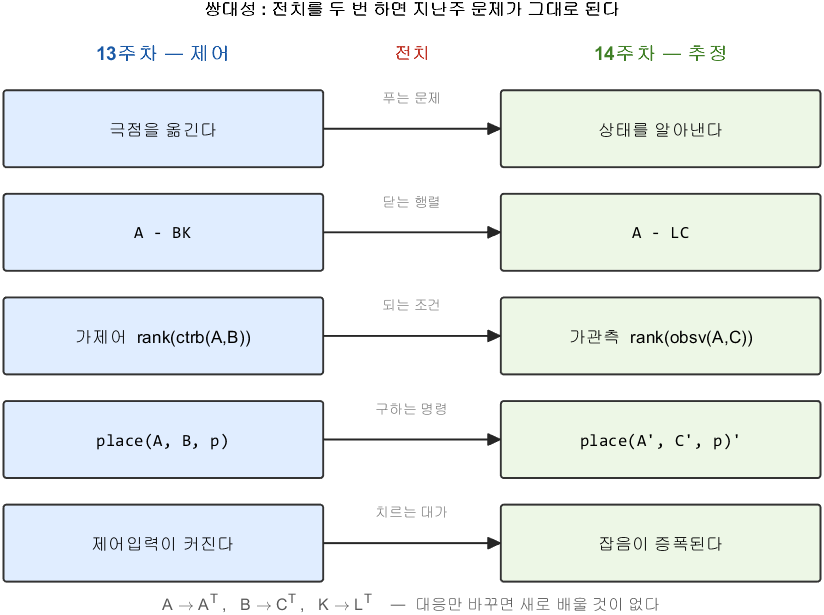

13주차와 14주차는 전치 관계

**그림 파일** `w14_duality.png` — `make_figures.m` 의 `fig_w14_duality` · 다시 만들려면 `make_figures('w14_duality')`

**만드는 곳** — `make_figures.m` 의 `fig_w14_duality` **직접 확인해 보려면** — `W14_01_observer.m` 의 **2절**이 전치를 한 단계씩 나누어 보여 줍니다

그림 해석

이것이 오늘 새로 배울 것이 적은 이유입니다. 문제가 새로운 것이 아니라, **지난주 문제를 전치해 놓은 것**입니다.

[Gp, p] = plant_dcmotor('position');
A = p.A; B = p.B; C = p.C; D = p.D;
p_obs = [-30 -34 -38];
L = place(A', C', p_obs)';
fprintf('C = %s  ->  각도만 잰다\n', mat2str(C));

C = [1 0 0]  ->  각도만 잰다


fprintf('rank(obsv) = %d / %d  ->  가관측\n', rank(obsv(A,C)), size(A,1));

rank(obsv) = 3 / 3  ->  가관측


fprintf('L = %s  (열벡터)\n', mat2str(round(L.', 2)));

L = [90 2351.98 32254.24]  (열벡터)


fprintf('eig(A - L*C) = %s\n', mat2str(round(sort(eig(A-L*C)).', 3)));

eig(A - L*C) = [-38 -34 -30]


## 4. 관측기가 정말 따라잡는가

실제 플랜트는 초기값이 있고, 관측기는 **아무것도 모르니 **$0$** 에서 출발**합니다. 그런데도 따라잡습니다.

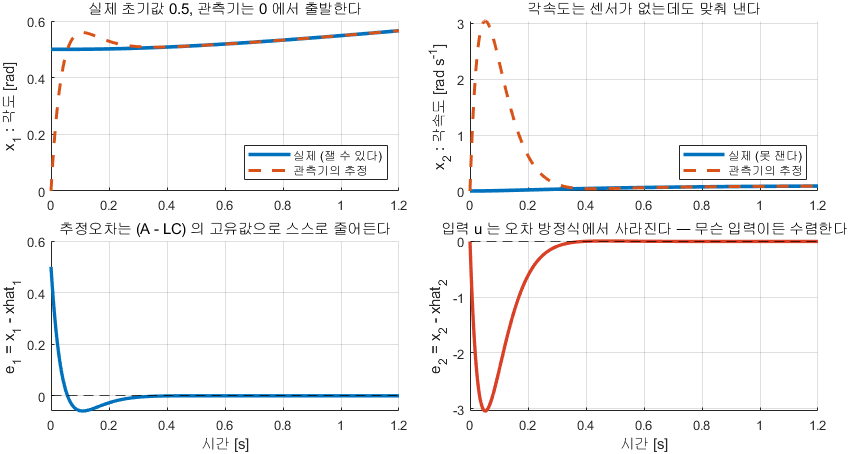

관측기는 0 에서 출발해도 따라잡는다

**그림 파일** `w14_converge.png` — `make_figures.m` 의 `fig_obs_converge` · 다시 만들려면 `make_figures('w14_converge')`

**만드는 곳** — `make_figures.m` 의 `fig_obs_converge` **직접 해 보려면** — `W14_01_observer.m` 의 **3절**, 또는 `W14_03_run_simulink.m` 이 Simulink 로 같은 실험을 합니다

그림 해석 — **위 두 칸이 상태, 아래 두 칸이 그 오차입니다**

**오른쪽 위 그림이 오늘의 요지입니다.** 각속도계가 없는데 각속도를 압니다. 각도를 계속 지켜보면서 모델을 함께 돌린 것만으로요.

## 5. 관측기 극을 얼마나 빠르게 잡는가

관례는 **제어기 극보다 **$2\sim5$** 배 빠르게** 입니다.

- 너무 느리면 — 추정이 따라오기 전에 제어기가 **틀린 값으로 일한다**

- 너무 빠르면 — $L$ 이 커져서 측정 잡음을 **그대로 증폭한다**

$L$ 이 크다는 것의 뜻을 생각해 보십시오. $L(y - C\hat{x})$ 에서 $L$ 이 크면 **측정값을 그만큼 세게 믿는다**는 것입니다. 측정값이 깨끗하면 좋지만, 잡음이 있으면 그 잡음도 세게 들어옵니다.

제어기 극을 $[-8\;\;-10\;\;-12]$ 로 잡았다면 관측기 극은 $[-24\;\;-30\;\;-36]$ 정도가 적당합니다.

$2\sim5$ 배라는 숫자가 어디서 나왔는지 직접 훑어 보겠습니다.

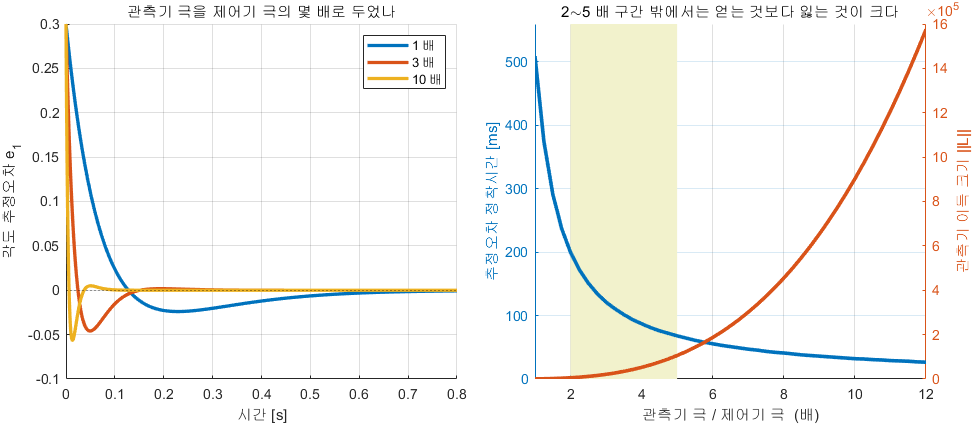

배속을 키우면 무엇이 좋아지고 무엇이 나빠지는가

**그림 파일** `w14_pole_speed.png` — `make_figures.m` 의 `fig_w14_pole_speed` · 다시 만들려면 `make_figures('w14_pole_speed')`

**만드는 곳** — `make_figures.m` 의 `fig_w14_pole_speed` **직접 바꿔 보려면** — `W14_01_observer.m` 의 **4절**에서 배속을 바꿔 가며 $L$ 과 수렴 속도를 확인합니다

그림 해석

관례의 근거가 여기 있습니다. $5$ 배를 넘어가면 **얻는 속도는 거의 없는데 **$L$** 만 커집니다.** 그림에서 두 곡선이 교차하는 자리가 대략 $5\sim6$ 배입니다. $L$ 이 크다는 것이 무슨 뜻인지는 다음 절에서 봅니다.

## 6. 대가 — 빠를수록 잡음이 커진다

**오늘의 맞바꿈입니다.**

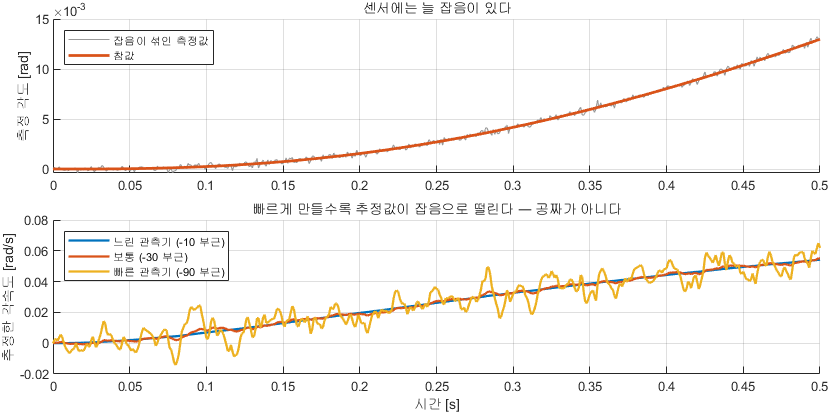

빠르게 만들수록 추정값이 잡음으로 떨린다

**그림 파일** `w14_obs_noise.png` — `make_figures.m` 의 `fig_obs_noise` · 다시 만들려면 `make_figures('w14_obs_noise')`

**만드는 곳** — `make_figures.m` 의 `fig_obs_noise` **직접 바꿔 보려면** — `W14_03_run_simulink.m` 의 **4절**에서 `noise_pwr` 을 키워 보십시오

그림 해석

**13주차와의 대칭을 보십시오.**

- 13주차 — 제어기 극을 왼쪽으로 보내면 **제어입력**이 커진다

- 14주차 — 관측기 극을 왼쪽으로 보내면 **잡음 증폭**이 커진다

두 대가가 정확히 짝을 이룹니다. 이것도 쌍대성입니다.

## 7. 분리원리 — 오늘의 하이라이트

이제 제어기와 관측기를 합칩니다.


$$u = -K\hat{x} + K_r r$$


진짜 $x$ 가 아니라 **추정값**을 씁니다. 추정이 틀린 동안에는 제어도 틀리니 서로 영향을 줄 것 같습니다.

**그런데 놀랍게도 서로 간섭하지 않습니다.**

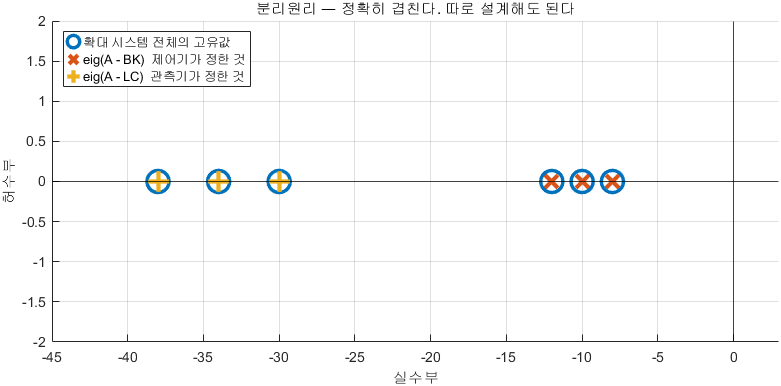

분리원리 — 정확히 겹친다

**그림 파일** `w14_separation.png` — `make_figures.m` 의 `fig_separation` · 다시 만들려면 `make_figures('w14_separation')`

**만드는 곳** — `make_figures.m` 의 `fig_separation` **직접 확인해 보려면** — `W14_02_separation.m` 의 **2절**

그림 해석

**이것이 분리원리입니다.** $K$ 는 $K$ 대로, $L$ 은 $L$ 대로 설계해도 됩니다. 이것이 없었다면 둘을 동시에 풀어야 했고, 13·14주차를 나눠 배울 수도 없었을 것입니다.

## 8. 왜 분리되는가 — 좌표를 바꿔 보면

증명은 좌표변환 한 번이면 끝납니다.

상태를 $[x;\;\hat{x}]$ 대신 $[x;\;e]$ 로 잡습니다. 여기서 $e = x - \hat{x}$ 입니다.


$$\dot{x} = Ax + Bu = Ax - BK\hat{x} = Ax - BK(x - e) = (A-BK)x + BKe$$



$$\dot{e} = (A - LC)\,e$$


행렬로 쓰면


$$\left[\begin{array}{c}\dot{x}\\ \dot{e}\end{array}\right] = \left[\begin{array}{cc} A-BK & BK\\ 0 & A-LC\end{array}\right] \left[\begin{array}{c}x\\ e\end{array}\right]$$


**왼쪽 아래가 **$0$** 입니다.** 이런 행렬을 블록 상삼각이라 하고, 그 고유값은 **대각 블록의 고유값을 합친 것**입니다.

물리적으로 읽으면 이렇습니다.

- 추정오차 $e$ 는 제어와 무관하게 스스로 줄어든다 (아랫줄에 $x$ 가 없다)

- 그 $e$ 가 위로 새어 들어가 $x$ 를 흔들지만, $e$ 가 죽으면 그 영향도 사라진다

즉 **오차는 제어를 신경 안 쓰고, 제어는 오차가 죽기를 기다리면 됩니다.**

## 9. 관측기 기반 제어기의 정체

관측기와 제어기를 합치면 결국 $y$** 를 받아 **$u$** 를 내놓는 전달함수 하나**입니다.


$$D(s) : \quad \dot{\hat{x}} = (A - BK - LC)\hat{x} + Ly, \qquad u = -K\hat{x}$$


## 9-0. $A - BK - LC$ 는 어디서 나왔는가 — 대입 한 번

세 글자가 한꺼번에 붙어 있어 복잡해 보이지만 **대입 한 번**이면 나옵니다.

우리가 가진 것은 두 줄뿐입니다.

**둘째를 첫째에 넣습니다.** $u$ 자리에 $-K\hat{x}$ 를 그대로 씁니다.


$$\dot{\hat{x}} = A\hat{x} + B\left(-K\hat{x}\right) + L y - LC\hat{x}$$


$\hat{x}$ 가 붙은 항이 셋입니다. 묶어냅니다.


$$\dot{\hat{x}} = \left(A - BK - LC\right)\hat{x} + L\,y$$


**세 글자가 각각 어디서 왔는지 보십시오.**

그리고 입력은 $y$ 하나, 출력은 $u$ 하나입니다. 즉 이 두 줄은 $y \to u$** 인 상태공간 모델**이고, 3주차의 공식으로 전달함수를 만들 수 있습니다.


$$D(s) = -K\left(sI - A + BK + LC\right)^{-1} L$$


앞의 $-K$ 는 출력식 $u = -K\hat{x}$ 의 $C$ 자리이고, 뒤의 $L$ 은 입력식의 $B$ 자리입니다. $D$ 항은 없습니다.

이것의 보드 선도를 그려 보면 재미있는 사실이 나옵니다 — **중간 주파수에서 위상을 올립니다.**

7주차와 11주차의 **Lead 보상기**가 하던 그 일입니다.

즉 상태공간이라는 전혀 다른 길로 왔는데, 결과물은 **우리가 이미 아는 물건**입니다. 10강 slide 75~77 의 결론이 이것입니다.

이 사실이 주는 안도감이 있습니다. 상태공간은 새로운 마법이 아니라, **같은 것을 다른 언어로 적는 방법**입니다.

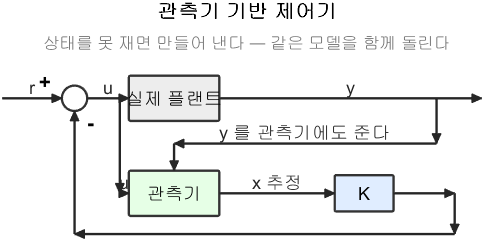

관측기 기반 제어기

**그림 파일** `loop_observer.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_observer')`

**만드는 곳** — `common/dg_loop.m` 을 `dg_loop('observer', ...)` 로 부릅니다

그림 해석

## 10. 진짜 상태를 쓴 것과 얼마나 다른가

가장 실용적인 질문입니다.

`W14_02_separation.m` 의 5절이 세 가지를 비교합니다.

읽는 법

- (a) 와 (b) 가 **완전히 겹칩니다** (차이 $10^{-14}$). 둘 다 $x(0)=0$ 이라 추정오차가 처음부터 $0$ 이기 때문입니다

- (c) 는 처음에 다릅니다. 관측기가 $0.3$ 을 모르기 때문입니다

- 그런데 관측기 극이 빨라서 금방 따라잡고, 그 뒤로는 (a) 와 같습니다

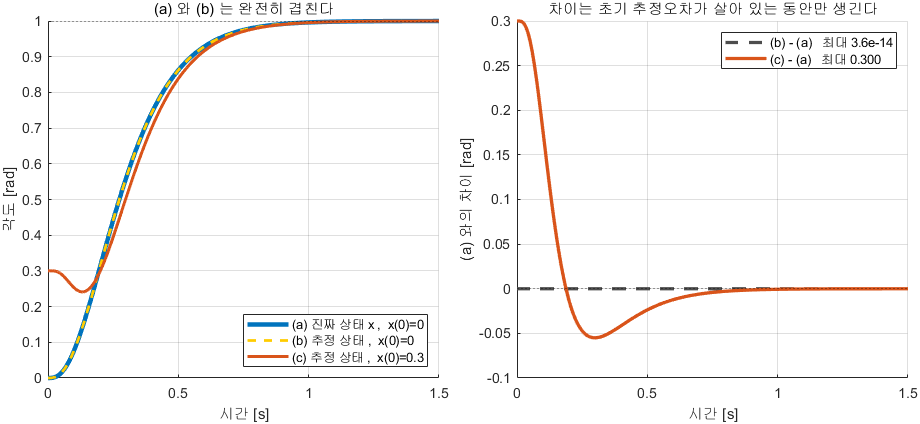

진짜 상태를 쓴 것과 추정 상태를 쓴 것

**그림 파일** `w14_true_vs_est.png` — `make_figures.m` 의 `fig_w14_true_vs_est` · 다시 만들려면 `make_figures('w14_true_vs_est')`

**만드는 곳** — `make_figures.m` 의 `fig_w14_true_vs_est` **직접 확인해 보려면** — `W14_02_separation.m` 의 **5절**이 위 표의 세 값을 그대로 출력합니다

그림 해석

**이것이 분리원리가 실무에서 뜻하는 것입니다.** 관측기를 충분히 빠르게 잡아 두면, 진짜 상태를 쓴 것과 거의 같습니다. 차이는 **초기 추정오차가 살아 있는 동안만** 생기고, 그 시간은 우리가 정합니다.

## 11. Simulink 로 실제와 추정을 나란히

모델 `W14_ObserverBased.slx` 를 열어 보십시오. 위아래 두 갈래입니다.

- **위쪽** — 실제 플랜트. 초기조건 $x_0$ 가 있다

- **아래쪽** — 관측기. 초기조건이 $0$ 이다. **아무것도 모른다**

그리고 **관측기로 들어가는 선이 **$u$** 와 **$y$** 두 개뿐**인지 직접 확인하십시오. 진짜 상태는 아무 데도 연결되어 있지 않습니다.

관측기는 State-Space 블록 하나로 구현했습니다.


$$\dot{\hat{x}} = (A - LC)\hat{x} + \left[\begin{array}{cc}B & L\end{array}\right] \left[\begin{array}{c}u\\ y\end{array}\right]$$


괄호를 풀면 $\dot{\hat{x}} = A\hat{x} + Bu + L(y - C\hat{x})$ 와 같습니다.

이 모델에는 오늘 처음 보는 블록이 하나 있습니다.

`Demux` — 묶여 있는 신호를 다시 갈라내는 블록

- 하는 일 — 여러 개가 묶인 신호선 하나를 받아 **여러 출력 포트로 나눈다**. 1주차에서 쓴 `Mux` 의 정반대다

- `Number of outputs` — 몇 갈래로 나눌지. 숫자 하나를 적으면 균등하게 나누고, `[1 3]` 처럼 벡터를 적으면 **첫 갈래는 1 개, 둘째 갈래는 3 개**로 나눈다

- 왜 필요한가 — 이 모델의 실제 플랜트는 $C$ 를 $\left[\begin{array}{c}C\\ I\end{array}\right]$ 로 두어 **측정값 **$y$** 와 진짜 상태 **$x$** 를 한 선에 함께** 내보낸다. 그런데 둘의 쓰임이 완전히 다르다

- $y$ — 관측기에 넣어 준다. **관측기가 볼 수 있는 유일한 것**

- $x$ — 그래프에만 쓴다. 우리가 채점하려고 몰래 보는 값이고, **관측기 쪽으로는 절대 가지 않는다**

- 그래서 `Demux` 의 출력 개수를 `[1 size(A,1)]` 로 두었다. 첫 포트가 $y$ 한 개, 둘째 포트가 상태 전부다. **이 갈라짐이 오늘 실험의 공정성을 보장합니다**

`W14_03_run_simulink.m` 을 실행하면 다음을 확인합니다.

**표를 가로로 읽으십시오.** 오른쪽으로 갈수록 빨리 따라잡지만 떨림이 함께 커집니다. 그래서 관례가 $2\sim5$ 배인 것입니다.

## 12. 한 학기 되짚기

열네 주 동안 온 길을 한 번에 봅니다.

**오른쪽 두 열을 세로로 읽어 보십시오.** 열네 주 내내 같은 문장이 반복됩니다 — **공짜는 없다.**

그중에서도 **거꾸로 선 진자 하나**가 네 주차를 관통했습니다.

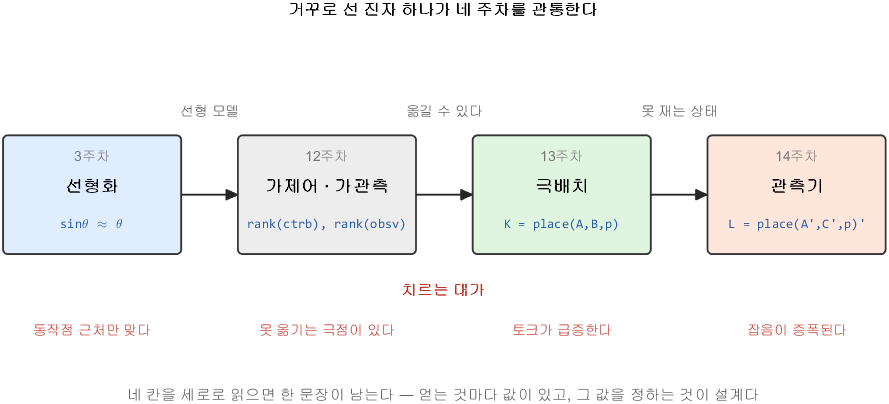

진자 하나로 이어진 네 주차

**그림 파일** `w14_semester_arc.png` — `make_figures.m` 의 `fig_w14_semester_arc` · 다시 만들려면 `make_figures('w14_semester_arc')`

**만드는 곳** — `make_figures.m` 의 `fig_w14_semester_arc` **직접 이어서 돌려 보려면** — `W03_03_pendulum_linearization.m`, `W12_02_ctrb_obsv.m`, `W13_03_pendulum_balance.m`, `W14_02_separation.m` 을 순서대로 실행하면 같은 진자가 네 번 나옵니다

그림 해석

왼쪽에서 오른쪽으로 읽으면 "무엇을 할 수 있게 되었는가" 이고, 아래 줄을 읽으면 "그 대신 무엇을 내주었는가" 입니다.

이 과목에서 가져갈 것이 하나라면 그것입니다. 제어는 마법이 아니라 **무엇을 주고 무엇을 얻을지 정하는 일**입니다.

## 11-1. 전치 트릭을 명령으로 확인한다

3절에서 유도한 $L = \mathrm{place}(A^T, C^T, p)^T$ 를 실제로 한 줄씩 나누어 보면 무엇이 일어나는지 분명해집니다.

`place(A', C', p)'` **에서 작은따옴표가 세 번 나옵니다.** 세 개를 다 쓰지 않으면 `L` 이 행벡터로 나와 뒤에서 크기가 안 맞습니다. 자주 하는 실수이므로 만든 직후 `size(L)` 로 확인하는 습관을 들이십시오.

[~, pC] = plant_dcmotor('position');
Ao = pC.A;  Co = pC.C;
p_obs = [-30 -34 -38];

Ad = Ao.';  Bd = Co.';
Kd = place(Ad, Bd, p_obs);
Lo = Kd.';

fprintf('1) Ad 크기 %s,  Bd 크기 %s\n', mat2str(size(Ad)), mat2str(size(Bd)));

1) Ad 크기 [3 3],  Bd 크기 [3 1]


fprintf('2) Kd 크기 %s  (행벡터)\n', mat2str(size(Kd)));

2) Kd 크기 [1 3]  (행벡터)


fprintf('3) L  크기 %s  (열벡터여야 합니다)\n', mat2str(size(Lo)));

3) L  크기 [3 1]  (열벡터여야 합니다)


fprintf('4) L = %s\n', mat2str(round(Lo.', 2)));

4) L = [90 2351.98 32254.24]



fprintf('\n원한 관측기 극 : %s\n', mat2str(p_obs));


원한 관측기 극 : [-30 -34 -38]


fprintf('eig(A - L*C)   : %s\n', mat2str(round(sort(eig(Ao - Lo*Co)).', 4)));

eig(A - L*C)   : [-38 -34 -30]



% 한 줄로 쓴 것과 같은지 확인
L_one = place(Ao.', Co.', p_obs).';
fprintf('한 줄로 쓴 결과와의 차이 : %.2e\n', max(abs(Lo - L_one)));

한 줄로 쓴 결과와의 차이 : 0.00e+00


## 13. 오늘의 정리

- 관측기는 **같은 모델을 컴퓨터에서 함께 돌리고, 출력 차이를 보고 고치는 것**

- 추정오차는 $\dot{e} = (A - LC)e$ 를 따른다. **입력과 무관하다**

- $L = \mathrm{place}(A^{T}, C^{T}, p_{obs})^{T}$ — 전치 트릭

- 조건은 **가관측**. 12주차에서 확인했다

- 관측기 극은 제어기 극보다 **2~5배 빠르게**

- 빠를수록 잘 따라잡지만 **잡음을 더 크게 증폭한다**

- **분리원리** — 확대 시스템의 고유값 $=$ $\mathrm{eig}(A-BK) \cup \mathrm{eig}(A-LC)$

- 그래서 제어기와 관측기를 **따로 설계해도 된다**

- 합쳐 놓고 보면 결국 **Lead 보상기와 닮은 물건**이다

## 14. 기말고사 안내와 마무리

15주차는 기말고사입니다. 범위는 **9~14주차**입니다.

준비할 것

- 각 주차의 강의노트 `0. 오늘 한 장 요약` 과 `오늘의 정리` 를 먼저 훑을 것

- 실습 스크립트를 **직접 돌려 볼 것**. 숫자를 눈으로 본 것이 오래 갑니다

- 숙제의 `TODO` 를 다시 채워 볼 것

그리고 마지막으로

이 과목은 "어떤 제어기가 정답인가" 를 가르치지 않았습니다. **무엇을 얻고 무엇을 잃을지 계산하는 법**을 가르쳤습니다.

현장에서 만날 시스템은 여기서 다룬 것보다 복잡할 것입니다. 그래도 물어볼 질문은 같습니다.

- 이 시스템은 안정한가. 여유는 얼마나 있는가

- 사양을 만족하는가. 만족하는 것 중 무엇이 가장 싼가

- **구동기가 그것을 낼 수 있는가**

- 센서가 그것을 잴 수 있는가. 없으면 만들어 낼 수 있는가

이 네 질문을 던질 수 있으면 이 과목의 목표는 이룬 것입니다.

한 학기 수고하셨습니다.